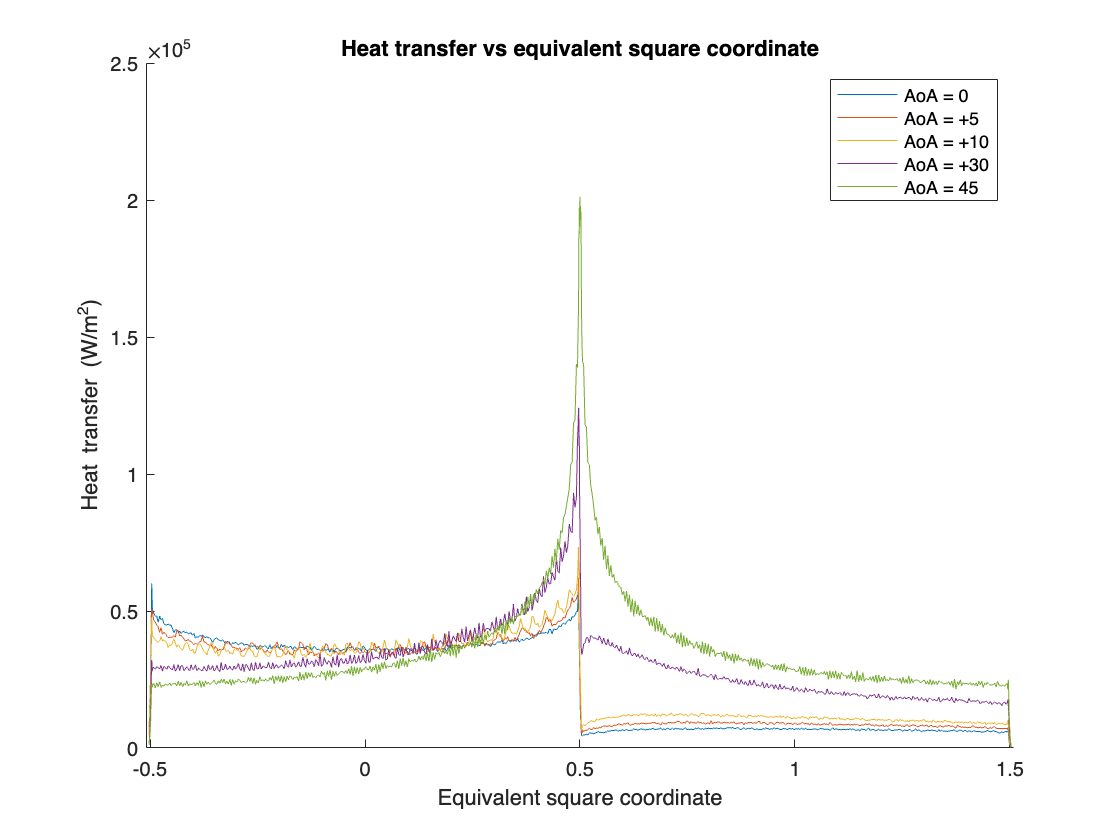

clear

sp=170;
u=1655;
cp=1.4;
tw=300;
t0=273;
H0=cp*t0+u^2/2;
hw=cp*tw;
rho=1.727e-4;
stden=rho * u * (H0 - hw);

D0 = readmatrix('./AoA_results/0.txt');
D0 = sortrows(D0(8:1279,1:10),1);
D0 = D0(1:651,:);
D0(:,11) = D0(:,10)./mean(D0(sp-5:sp+5,10));
D0(:,12) = D0(:,10)./stden;

Dplus5 = readmatrix('./AoA_results/plus5.txt');
Dplus5 = sortrows(Dplus5(8:1279,1:10),1);
Dplus5 = Dplus5(1:651,:);
Dplus5(:,11) = Dplus5(:,10)./mean(Dplus5(sp-5:sp+5,10));
Dplus5(:,12) = Dplus5(:,10)./stden;
    
Dplus10 = readmatrix('./AoA_results/plus10.txt');
Dplus10 = sortrows(Dplus10(8:1279,1:10),1);
Dplus10 = Dplus10(1:651,:);
Dplus10(:,11) = Dplus10(:,10)./mean(Dplus10(sp-5:sp+5,10));
Dplus10(:,12) = Dplus10(:,10)./stden;

Dplus30 = readmatrix('./AoA_results/plus30.txt');
Dplus30 = sortrows(Dplus30(8:1279,1:10),1);
Dplus30 = Dplus30(1:651,:);
Dplus30(:,11) = Dplus30(:,10)./mean(Dplus30(sp-5:sp+5,10));
Dplus30(:,12) = Dplus30(:,10)./stden;

Dminus5 = readmatrix('./AoA_results/minus5.txt');
Dminus5 = sortrows(Dminus5(8:1279,1:10),1);
Dminus5 = Dminus5(1:651,:);
Dminus5(:,11) = Dminus5(:,10)./mean(Dminus5(sp-5:sp+5,10));
Dminus5(:,12) = Dminus5(:,10)./stden;
    
Dminus10 = readmatrix('./AoA_results/minus10.txt');
Dminus10 = sortrows(Dminus10(8:1279,1:10),1);
Dminus10 = Dminus10(1:651,:);
Dminus10(:,11) = Dminus10(:,10)./mean(Dminus10(sp-5:sp+5,10));
Dminus10(:,12) = Dminus10(:,10)./stden;

Dminus30 = readmatrix('./AoA_results/minus30.txt');
Dminus30 = sortrows(Dminus30(8:1279,1:10),1);
Dminus30 = Dminus30(1:651,:);
Dminus30(:,11) = Dminus30(:,10)./mean(Dminus30(sp-5:sp+5,10));
Dminus30(:,12) = Dminus30(:,10)./stden;

D45 = readmatrix('./AoA_results/45.txt');
D45 = sortrows(D45(8:1279,1:10),1);
D45 = D45(1:651,:);
D45(:,11) = D45(:,10)./mean(D45(sp-5:sp+5,10));
D45(:,12) = D45(:,10)./stden;

coords=coords('./AoA_results/squareroundhp2.txt');
coords = coords(1:651,:);


%positive

figure
hold on
plot(coords(:,2),D0(:,10))
plot(coords(:,2),Dplus5(:,10))
plot(coords(:,2),Dplus10(:,10))
plot(coords(:,2),Dplus30(:,10))
plot(coords(:,2),D45(:,10))
legend('AoA = 0','AoA = +5','AoA = +10','AoA = +30','AoA = 45')
xlabel('Equivalent square coordinate')
ylabel('Heat transfer (W/m^2)')
xlim([-0.51, 1.51])
title('Heat transfer vs equivalent square coordinate')

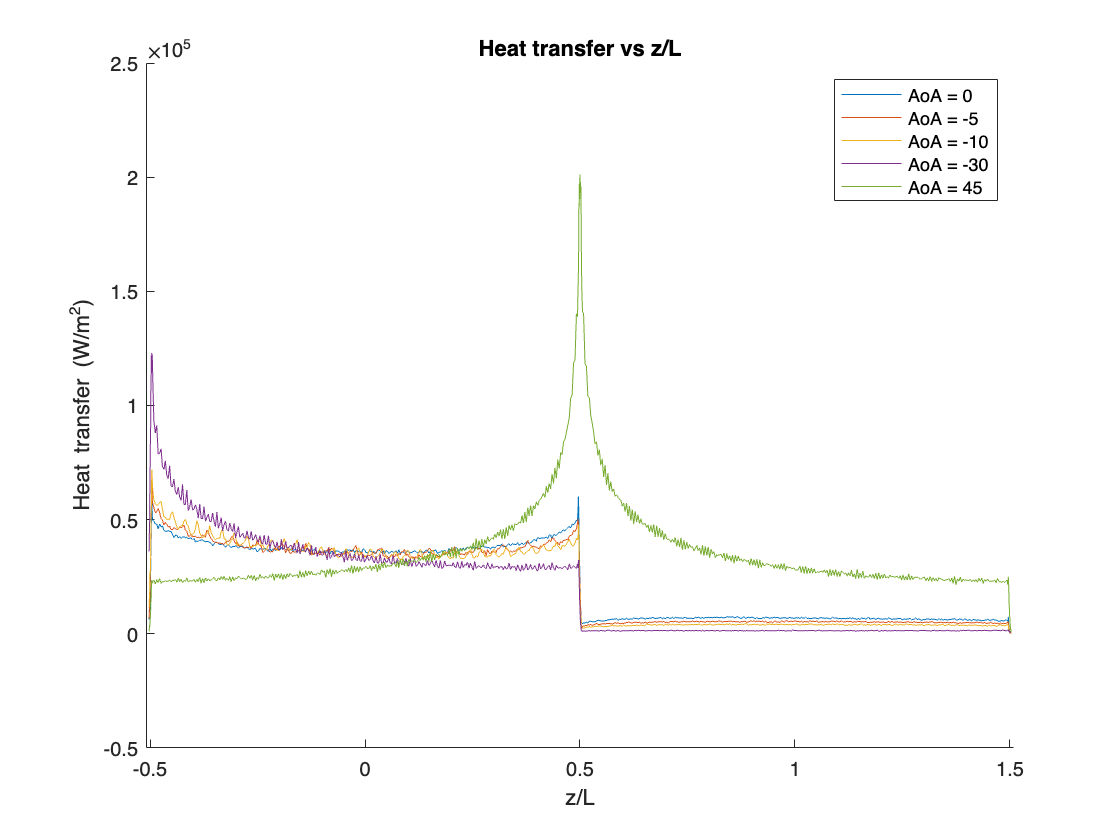


% figure
% hold on
% plot(coords(:,2),Dplus5(:,11))
% plot(coords(:,2),Dplus5(:,11))
% plot(coords(:,2),Dplus10(:,11))
% plot(coords(:,2),Dplus30(:,11))
% plot(coords(:,2),D45(:,11))
% legend('AoA = 0','AoA = +5','AoA = +10','AoA = +30','AoA = 45')
% xlabel('z/L')
% ylabel('Normalised heat transfer')
% xlim([-0.51, 1.51])
% title('Normalised heat transfer vs z/L')

% figure
% hold on
% plot(coords(:,2),D0(:,12))
% plot(coords(:,2),Dplus5(:,12))
% plot(coords(:,2),Dplus10(:,12))
% plot(coords(:,2),Dplus30(:,12))
% plot(coords(:,2),D45(:,12))
% legend('AoA = 0','AoA = +5','AoA = +10','AoA = +30','AoA = 45')
% xlabel('Equivalent square coordinate')
% ylabel('Modified Stanton number')
% xlim([-0.51, 1.51])
% title('Modified Stanton number vs equivalent square coordinate')


%negative

figure
hold on
plot(coords(:,2),D0(:,10))
plot(coords(:,2),Dminus5(:,10))
plot(coords(:,2),Dminus10(:,10))
plot(coords(:,2),Dminus30(:,10))
plot(coords(:,2),D45(:,10))
legend('AoA = 0','AoA = -5','AoA = -10','AoA = -30','AoA = 45')
xlabel('z/L')
ylabel('Heat transfer (W/m^2)')
xlim([-0.51, 1.51])
title('Heat transfer vs z/L')


% figure
% hold on
% plot(coords(:,2),Dminus5(:,11))
% plot(coords(:,2),Dminus5(:,11))
% plot(coords(:,2),Dminus10(:,11))
% plot(coords(:,2),Dminus30(:,11))
% plot(coords(:,2),D45(:,11))
% legend('AoA = 0','AoA = -5','AoA = -10','AoA = -30','AoA = 45')
% xlabel('z/L')
% ylabel('Normalised heat transfer')
% xlim([-0.51, 1.51])
% title('Normalised heat transfer vs z/L')

% figure
% hold on
% plot(coords(:,2),D0(:,12))
% plot(coords(:,2),Dminus5(:,12))
% plot(coords(:,2),Dminus10(:,12))
% plot(coords(:,2),Dminus30(:,12))
% plot(coords(:,2),D45(:,12))
% legend('AoA = 0','AoA = -5','AoA = -10','AoA = -30','AoA = 45')
% xlabel('Equivalent square coordinate')
% ylabel('Modified Stanton number')
% xlim([-0.51, 1.51])
% title('Modified Stanton number vs equivalent square coordinate')